# Step 1: Explanatory analysis

### Descriptive statistics

Compute the following statisitics for each time series:

- minimum

- maximum 

- mean

- median

- variance

- skewness

- kurtosis

% data path (change country name if required)
file = 'data/china.csv';
% read data
data = readtable(file);
format compact
t =  data.Properties.VariableNames;
% use (our own) describe function 
stats = describe(data);

### Histogram plots

They are used to understand the underlying data distribution

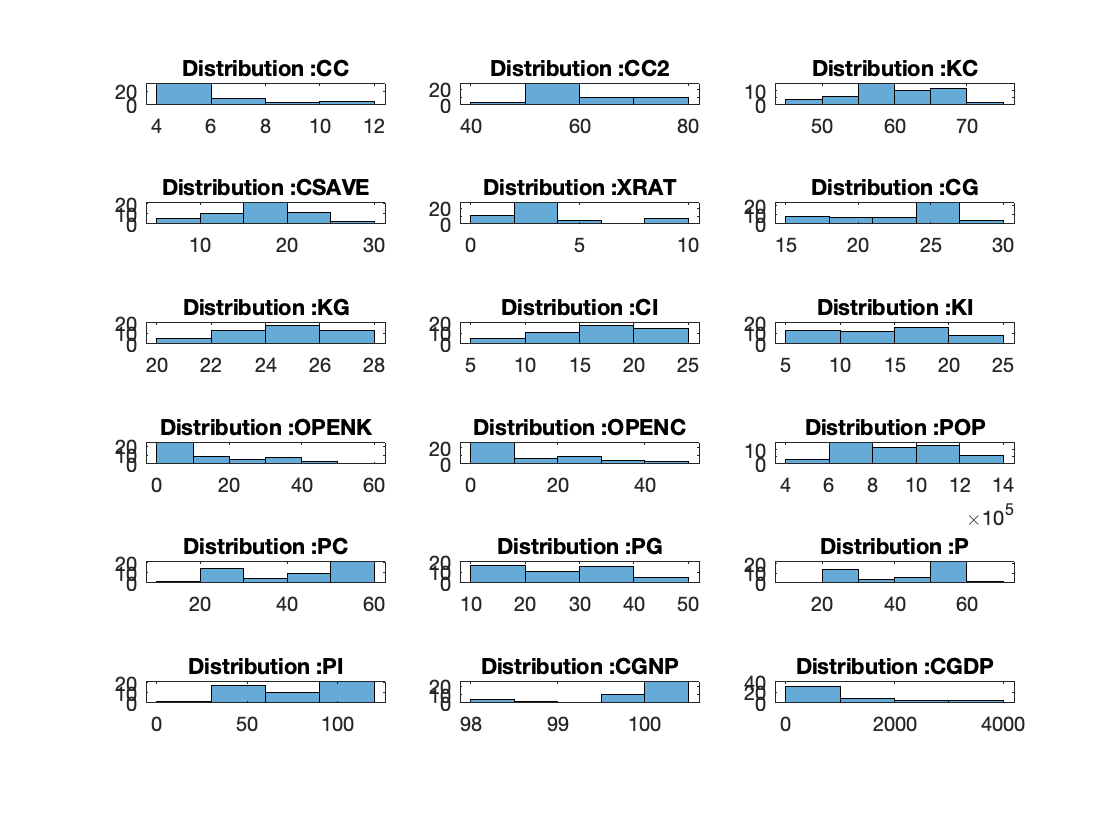

figure
for col = 2:size(data,2) % iterate on all cols
    subplot(6,3,col-1);
    histogram(data.(col));
    % uncomment these lines to have log/log plot
    %set(gca,'YScale','log')
    %set(gca,'XScale','log')
    title(strcat('Distribution :',data.Properties.VariableNames{col}));
end

### Correlation analysis

Study how correlated the independant variable are. Let's visualise the results in a heatmap.

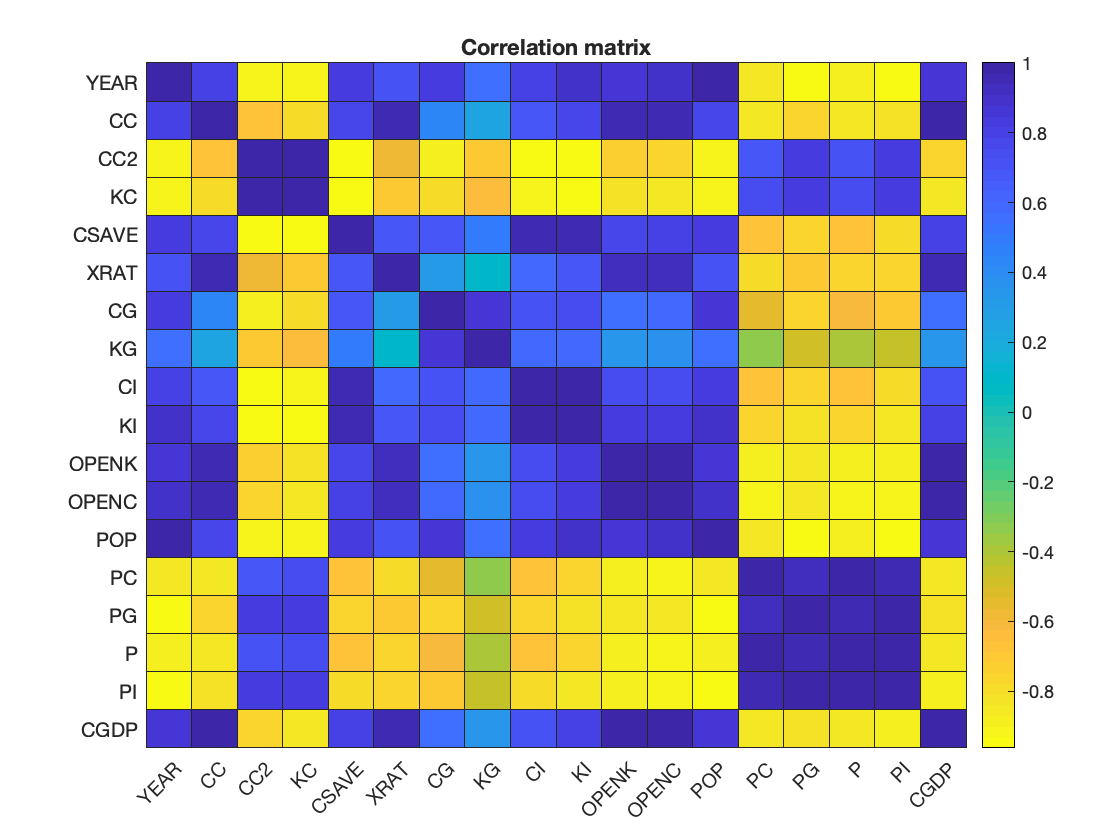

% remove CGNP and filter nans 
matrix = preprocess(file);
% compute correlation matrix
corr = corrcoef(matrix(:,2:end));
figure
% plot heat map
h = heatmap(corr,"Colormap",flipud(colormap('parula')));
h.Title  = 'Correlation matrix';
feature_names = ["YEAR","CC","CC2","KC","CSAVE","XRAT","CG","KG","CI","KI","OPENK","OPENC","POP","PC","PG","P","PI","CGDP"];
h.XDisplayLabels = feature_names;
h.YDisplayLabels = feature_names;


% data seems colinear => test condition number (without GDP)
X = matrix(:,1:end-1);
s = colinearity_analysis(X);

s.condition_number

ans = 5.7343e+13

### Scatter plot between each feature and GDP

In this basic data exploration, we also wanted to see if we could actually build a model to predict GDP. That's why we decided to use a scatter plot to visualise the relationship between each feature and GDP.

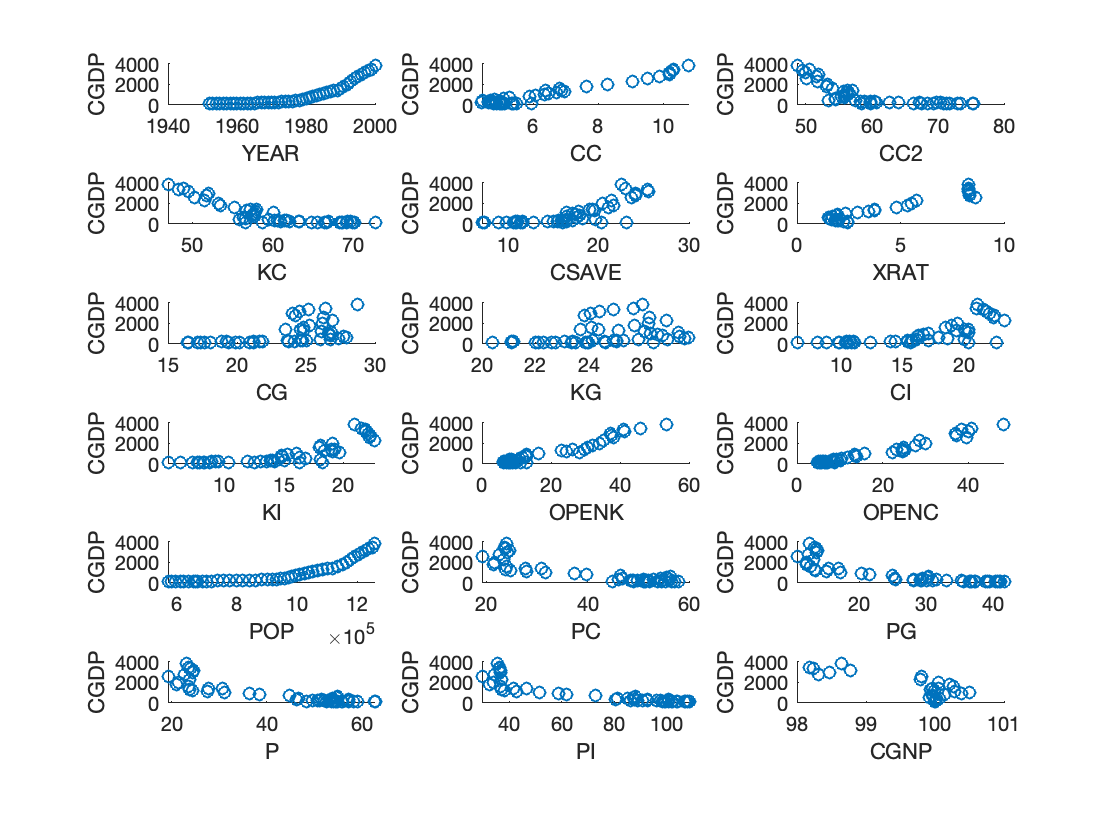

figure
for col = 1:size(data,2)-1
    subplot(6,3,col);
    % use scatter plot
    scatter(data.(col),data.CGDP);
    xlabel(data.Properties.VariableNames{col});
    ylabel('CGDP');
end